clear all
clc
clf
warning off;

%% ===================== Batch Patient List & Global Settings =====================
patients = {'011','012','019','025','036','041','052','054','085','088','099'}; 
num_patients = length(patients);
D_total = zeros(num_patients, 1);
D_sum_times = cell(num_patients, 1);
all_fitted_params = zeros(num_patients, 15);  
param_names = {'r1','r2','r3','r4','d1','d2','d3','d4','a1','a2','K','x10','x20','x30','x40'};
fit_errors = zeros(num_patients,1);

% Desktop file path
desktopPath = fullfile(getenv('USERPROFILE'), 'Desktop');
data_root = fullfile(desktopPath, 'prostate cancer clinical treatment data', 'Bruchovsky_et_al');

figure('Position', [100, 100, 1400, 900]);
annotation('textbox', [0.45, 0.02, 0.1, 0.05], 'String', 'Month', ...
    'EdgeColor', 'none', 'FontSize', 14, 'HorizontalAlignment', 'center');
annotation('textbox', [0.06, 0.5, 0.05, 0.1], 'String', 'N (Normalized PSA)', ...
    'EdgeColor', 'none', 'FontSize', 14, 'Rotation', 90, 'HorizontalAlignment', 'center');

%% ===================== ODE Model Function =====================
function dydt = model(t, y, r1, r2, r3, r4, d1, d2, d3, d4, a1, a2, K, D_seq, F_seq)
    x1 = y(1); x2 = y(2); x3 = y(3); x4 = y(4);
    idx = round(t); idx = max(1, min(idx, length(D_seq)));
    D_t = D_seq(idx); F_t = F_seq(idx);
    dydt = zeros(4,1);
    
    x_sum = max(x1+x2+x3+x4, 1e-6);
    dydt(1) = r1*x1*(1-x_sum/K) * max(1-a1*D_t-a2*F_t, 0) - d1*x1;
    dydt(2) = r2*x2*(1-x_sum/K) * max(1-a2*F_t, 0) - d2*x2;
    dydt(3) = r3*x3*(1-x_sum/K) * max(1-a1*D_t, 0) - d3*x3;
    dydt(4) = r4*x4*(1-x_sum/K) - d4*x4;
end

%% ===================== Objective Function =====================
function error = objective(params, t, y_data, D, F)
    r1=params(1);r2=params(2);r3=params(3);r4=params(4);
    d1=params(5);d2=params(6);d3=params(7);d4=params(8);
    a1=params(9);a2=params(10);K=params(11);
    x10=params(12);x20=params(13);x30=params(14);x40=params(15);
    
    r1_min = 0.1;
    r1_max = 0.8;
    
    if any(params < 0) || ...
       r1 < r1_min || r1 > r1_max || ...
       r2 >= r1 || r3 >= r2 || r4 >= r3 || r4 <= 0.5*r1 || ...
       K<=1.2 || K>=2 || ...
       a1<=1 || a1>=3 || a2<=1 || a2>=3   
        error = 1e6; return;
    end
    
    bound1 = r1*(K-1.2)/K;
    bound2 = r2*(K-1.2)/K;
    bound3 = r3*(K-1.2)/K;
    bound4 = r4*(K-1.2)/K;
    
    if d1<=0 || d2<=0 || d3<=0 || d4<=0 ...
       || d1 >= bound1 || d2 >= bound2 || d3 >= bound3 || d4 >= bound4
        error = 1e6; return;
    end
    
    sum0 = x10+x20+x30+x40;
    if abs(sum0 - y_data(1)) > 0.1*y_data(1) || sum0 < 1e-6
        error = 1e6; return;
    end
    
    try
        y0 = [x10,x20,x30,x40];
        opts = odeset('AbsTol',1e-8,'RelTol',1e-6,'MaxStep',1);
        [t_sol,sol] = ode45(@(t,y) model(t,y,r1,r2,r3,r4,d1,d2,d3,d4,a1,a2,K,D,F), t, y0, opts);
        
        if size(sol,1) ~= length(t)
            error = 1e6; return;
        end
        
        y_pred = sum(sol,2);
        error = sum((y_pred - y_data).^2);
    catch
        error = 1e6;
    end
end

%% ===================== Nonlinear Constraint Function =====================
function [c, ceq] = nonlcon(params)
    r1=params(1); r2=params(2); r3=params(3); r4=params(4);
    d1=params(5); d2=params(6); d3=params(7); d4=params(8);
    a1=params(9); a2=params(10);
    K=params(11);
    x10=params(12);x20=params(13);x30=params(14);x40=params(15);
    
    delta = 1e-4;
    N0 = x10+x20+x30+x40;
    
    b1 = r1*(K-1.2)/K;
    b2 = r2*(K-1.2)/K;
    b3 = r3*(K-1.2)/K;
    b4 = r4*(K-1.2)/K;
    
    c = [
        r2 - r1 + delta;
        r3 - r2 + delta;
        r4 - r3 + delta;
        0.5*r1 - r4 + delta;
        
        d1 - 0.5*r1 + delta;
        d2 - 0.5*r2 + delta;
        d3 - 0.5*r3 + delta;
        d4 - 0.5*r4 + delta;
        
        d1 - b1 + delta;
        d2 - b2 + delta;
        d3 - b3 + delta;
        d4 - b4 + delta;
        
        1.2 - K + delta;
        K - 2 + delta;
        
        x20 - x10 + delta;
        x30 - x10 + delta;
        x40 - x10 + delta;
        x40 - x20 + delta;
        x40 - x30 + delta;
        
        0.001*N0 - x40 + delta;
        x40 - 0.01*N0 + delta;
        
        1 - a1 + delta;
        a1 - 3 + delta;
        1 - a2 + delta;
        a2 - 3 + delta;
        
        -d1 + delta;
        -d2 + delta;
        -d3 + delta;
        -d4 + delta;
    ];
    ceq = [];
end

%% ===================== Iterate Each Patient =====================
for idx = 1:num_patients
    fprintf('\n=========================================\n');
    fprintf('Processing Patient: %s  |  Optimization Times: 100\n', patients{idx});
    fprintf('=========================================\n');
    
    filename = fullfile(data_root, ['patient', patients{idx}, '.txt']);
    dataTable = readtable(filename, 'Delimiter', ',');
    
    B = table2array(dataTable(:, 3:10));
    data = B;
    N = size(data,1);
    t = (1:N)';

    y = data(:,3);
    x_idx = 1:length(y);
    nan_idx = isnan(y);
    y_filled = y;
    y_filled(nan_idx) = interp1(x_idx(~nan_idx), y(~nan_idx), x_idx(nan_idx), 'linear','extrap');
    data(:,3) = y_filled;

    target_cols = [1,2];
    treat_col = 6;
    for col = target_cols
        for i = 1:N
            if ~isnan(data(i,col))
                continue;
            end
            treat_state = data(i,treat_col);
            if treat_state == 0
                data(i,col) = 0;
            else
                s = max(1, i-3); e = min(N, i+3);
                win = data(s:e, col);
                valid = win(~isnan(win) & win~=0);
                if ~isempty(valid)
                    data(i,col) = mode(valid);
                else
                    data(i,col) = 0;
                end
            end
        end
    end

    norm_fun = @(x) (x-min(x))/(max(x)-min(x)+1e-6);
    data(:,1) = norm_fun(data(:,1));
    data(:,2) = norm_fun(data(:,2));
    data(:,3) = norm_fun(data(:,3));

    y_data = data(:,3);
    D = data(:,1);
    F = data(:,2);
    D_total(idx) = sum(D);
    temp_idx = find(cumsum(D)==D_total(idx), 1, 'last');
    
    if isempty(temp_idx)
        D_sum_times{idx} = N;
    else
        D_sum_times{idx} = temp_idx;
    end

    t_fit = t;
    y_fit = y_data;
    D_fit = D;
    F_fit = F;

    y0_real = y_data(1);
    N0 = y0_real;  
    x40_low  = 0.00001 * N0;
    x40_high = 0.001 * N0;

    r1_min = 0.1;
    r1_max = 0.8;
    
    lb = [r1_min, 0.5*r1_min+0.01, 0.5*r1_min+0.005, 0.5*r1_min, ...
          1e-6,1e-6,1e-6,1e-6, ...   
          1,1,1.2, ...
          0.1,0.001,0.001, x40_low];
      
    ub = [r1_max, r1_max-0.01, r1_max-0.02, r1_max-0.03, ...
          0.5*r1_max, 0.5*r1_max, 0.5*r1_max, 0.5*r1_max, ...
          3,3,2.0, ...
          1,0.5,0.5, x40_high];
    
    best_err = 1e6;
    best_params = [];
    num_trials = 100;  

    for trial = 1:num_trials
        if mod(trial,10) == 0
            fprintf('  Optimization Trial %d/%d\n', trial, num_trials);
        end
        
        r1 = r1_min + (r1_max - r1_min)*rand;
        r2 = r1*0.95 - 0.01 + 0.02*rand;
        r3 = r2*0.95 - 0.01 + 0.02*rand;
        r4 = r3*0.95 - 0.01 + 0.02*rand;
        r4 = max(r4, 0.5*r1 + 0.001);

        d1 = 1e-6 + (0.5*r1 - 1e-5)*rand;
        d2 = 1e-6 + (0.5*r2 - 1e-5)*rand;
        d3 = 1e-6 + (0.5*r3 - 1e-5)*rand;
        d4 = 1e-6 + (0.5*r4 - 1e-5)*rand;

        a1 = 1 + 2*rand;
        a2 = 1 + 2*rand;
        
        K = 1.2 + 0.8*rand;

        x10 = y0_real * (0.5 + 0.4*rand);
        x20 = y0_real * (0.001 + 0.1*rand);
        x30 = y0_real * (0.001 + 0.08*rand);
        x40 = x40_low + (x40_high - x40_low) * rand;

        scale = y0_real / (x10+x20+x30+x40);
        x10 = x10*scale;
        x20 = x20*scale;
        x30 = x30*scale;
        x40 = x40*scale;

        initial_guess = [r1,r2,r3,r4, d1,d2,d3,d4, a1,a2,K, x10,x20,x30,x40];

        options = optimset(...
            'Display','off', ...
            'MaxFunEvals',1e5, ...
            'MaxIter',1e5, ...
            'TolFun',1e-8, ...
            'TolX',1e-5, ...
            'DiffMinChange',0.00005, ...
            'DiffMaxChange',0.0001);

        try
            fitted_params = fmincon(@(p) objective(p,t_fit,y_fit,D_fit,F_fit), ...
                initial_guess,[],[],[],[],lb,ub,@nonlcon,options);
            err = objective(fitted_params,t_fit,y_fit,D_fit,F_fit);
            if err < best_err
                best_err = err;
                best_params = fitted_params;
            end
        catch
            continue;
        end
    end

    mse_fit = NaN;
    opts = odeset('AbsTol',1e-8,'RelTol',1e-6,'MaxStep',1);
    if isempty(best_params)
        fprintf('Patient %s optimization failed, default parameters applied\n', patients{idx});
        r1_def = 0.45;
        r2_def = 0.38; r3_def = 0.32; r4_def = 0.5*r1_def+0.01;
        a1_def = 2.0; 
        a2_def = 2.0;
        x40_def = 0.005 * N0;
        best_params = [r1_def,r2_def,r3_def,r4_def, ...
            0.2*r1_def,0.2*r2_def,0.2*r3_def,0.2*r4_def,...
            a1_def,a2_def,1.6, ...
            y0_real*0.9, y0_real*0.06, y0_real*0.03, x40_def];
        all_fitted_params(idx, :) = NaN(1,15);
        fit_errors(idx) = NaN;
    else
        all_fitted_params(idx, :) = best_params;
        y0_fit = best_params(12:15);
        [~,sol_fit] = ode45(@(t,y) model(t,y,best_params(1),best_params(2),best_params(3),best_params(4),...
            best_params(5),best_params(6),best_params(7),best_params(8),...
            best_params(9),best_params(10),best_params(11),D_fit,F_fit), t_fit, y0_fit, opts);
        yp_fit = sum(sol_fit,2);
        mse_fit = mean((yp_fit - y_fit).^2);
        fit_errors(idx) = mse_fit;
        fprintf('Patient %s completed | MSE: %.4f | a1=%.4f, a2=%.4f | x40=%.4f | r1=%.4f\n',...
            patients{idx}, mse_fit, best_params(9),best_params(10),best_params(15),best_params(1));
    end

    row = ceil(idx/4);      
    col = mod(idx-1,4)+1;
    subplot(4,4,idx,'Position',[0.07+0.22*(col-1), 0.75-0.22*(row-1), 0.19, 0.17]);
    hold on; grid on; box on;

    plot(t, y_data, 'bo-','LineWidth',1.2,'MarkerSize',3);

    for i=1:N
        if D(i)>1e-3
            patch([i-0.5,i+0.5,i+0.5,i-0.5],[1.2,1.2,1.35,1.35],'b','FaceAlpha',D(i),'EdgeColor','none');
        end
        if F(i)>1e-3
            patch([i-0.5,i+0.5,i+0.5,i-0.5],[1.35,1.35,1.5,1.5],'r','FaceAlpha',F(i),'EdgeColor','none');
        end
    end

    try
        y0 = best_params(12:15);
        [t_sol,sol] = ode45(@(t,y) model(t,y,...
            best_params(1),best_params(2),best_params(3),best_params(4),...
            best_params(5),best_params(6),best_params(7),best_params(8),...
            best_params(9),best_params(10),best_params(11),D,F), t, y0, opts);
        plot(t_sol, sum(sol,2),'r-','LineWidth',2);
        plot(t_sol, sol(:,1),'c--','LineWidth',1);
        plot(t_sol, sol(:,2),'g--','LineWidth',1);
        plot(t_sol, sol(:,3),'m--','LineWidth',1);
        plot(t_sol, sol(:,4),'k--','LineWidth',1);
    catch
    end

    end_time = D_sum_times{idx};
    if ~isempty(end_time) && end_time >= 1 && end_time <= N
        xline(end_time, 'k--', 'LineWidth',1.5);
        text(end_time, 1.42, num2str(end_time), ...
             'FontSize',7,'Color','k','HorizontalAlignment','center','BackgroundColor','w');
    end

    title({['ID ',patients{idx}],['MSE: ',num2str(mse_fit,'%.2f')]},'FontSize',8);
    ylim([0,1.55]);
    set(gca,'FontSize',8);
    if row<4, set(gca,'XTickLabel',[]); end
    if col>1, set(gca,'YTickLabel',[]); end
    hold off;
end

Processing Patient: 011  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 011 completed | MSE: 0.0148 | a1=1.2048, a2=2.9985 | x40=0.0000 | r1=0.6168


Processing Patient: 012  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 012 completed | MSE: 0.0280 | a1=1.4717, a2=2.0782 | x40=0.0009 | r1=0.4314


Processing Patient: 019  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 019 completed | MSE: 0.0773 | a1=2.2355, a2=1.9336 | x40=0.0000 | r1=0.6234


Processing Patient: 025  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 025 completed | MSE: 0.0913 | a1=1.4622, a2=2.7852 | x40=0.0000 | r1=0.6891


Processing Patient: 036  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 036 completed | MSE: 0.0239 | a1=1.9458, a2=2.1876 | x40=0.0000 | r1=0.7199


Processing Patient: 041  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 041 completed | MSE: 0.2514 | a1=2.1796, a2=2.7485 | x40=0.0010 | r1=0.5662


Processing Patient: 052  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 052 completed | MSE: 0.0498 | a1=2.0203, a2=2.0848 | x40=0.0000 | r1=0.5478


Processing Patient: 054  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 054 completed | MSE: 0.0151 | a1=1.3545, a2=1.8403 | x40=0.0000 | r1=0.5252


Processing Patient: 085  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 085 completed | MSE: 0.0676 | a1=1.7683, a2=1.6975 | x40=0.0001 | r1=0.6499


Processing Patient: 088  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 088 completed | MSE: 0.0250 | a1=2.5368, a2=2.4498 | x40=0.0000 | r1=0.5546


Processing Patient: 099  |  Optimization Times: 100


  Optimization Trial 10/100
  Optimization Trial 20/100
  Optimization Trial 30/100
  Optimization Trial 40/100
  Optimization Trial 50/100
  Optimization Trial 60/100
  Optimization Trial 70/100
  Optimization Trial 80/100
  Optimization Trial 90/100
  Optimization Trial 100/100


Patient 099 completed | MSE: 0.0521 | a1=2.5307, a2=1.9413 | x40=0.0000 | r1=0.5910


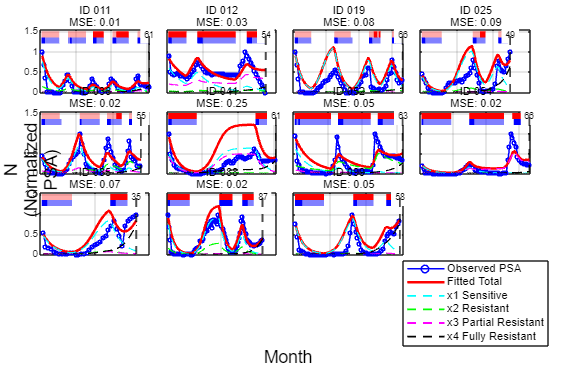


%% ===================== Legend =====================
subplot(4,4,16);
axis off;
hold on;
h1 = plot(NaN,NaN,'bo-','LineWidth',1.2);
h2 = plot(NaN,NaN,'r-','LineWidth',2);
h3 = plot(NaN,NaN,'c--','LineWidth',1.5);
h4 = plot(NaN,NaN,'g--','LineWidth',1.5);
h5 = plot(NaN,NaN,'m--','LineWidth',1.5);
h6 = plot(NaN,NaN,'k--','LineWidth',1.5);
legend([h1,h2,h3,h4,h5,h6],...
    {'Observed PSA','Fitted Total','x1 Sensitive','x2 Resistant','x3 Partial Resistant','x4 Fully Resistant'},...
    'Location','best','FontSize',9);
title('Population Subgroup Legend');
hold off;

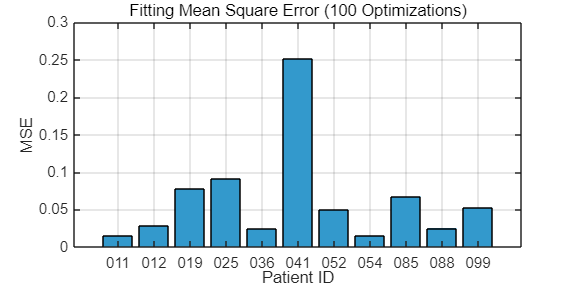


%% ===================== MSE Bar Plot =====================
figure('Position', [500, 200, 800, 400]);
bar(1:num_patients, fit_errors, 'FaceColor',[0.2 0.6 0.8],'EdgeColor','k');
xticks(1:num_patients);
xticklabels(patients);
xlabel('Patient ID');
ylabel('MSE');
title('Fitting Mean Square Error (100 Optimizations)');
grid on;
set(gca,'FontSize',12);


%% ===================== Summary Output =====================
SummaryTable = table(patients', D_total, D_sum_times,...
    'VariableNames',{'PatientID','Total_Dosage','Termination_Time'});
disp('==================== Treatment Summary ====================');

==================== Treatment Summary ====================


disp(SummaryTable);

    PatientID    Total_Dosage    Termination_Time
    _________    ____________    ________________

     {'011'}         25.5             {[61]}     
     {'012'}           25             {[54]}     
     {'019'}         21.5             {[66]}     
     {'025'}         14.5             {[49]}     
     {'036'}           22             {[55]}     
     {'041'}           16             {[61]}     
     {'052'}         31.5             {[63]}     
     {'054'}           29             {[66]}     
     {'085'}         12.5             {[35]}     
     {'088'}           35             {[87]}     
     {'099'}           22             {[58]}     




fprintf('\n\n==================== All Patient Fitted Parameters ====================\n');



==================== All Patient Fitted Parameters ====================


param_table = array2table(all_fitted_params, 'VariableNames', param_names);
param_table = addvars(param_table, patients', 'Before', 1, 'NewVariableNames', 'PatientID');
disp(param_table);

    PatientID      r1         r2         r3         r4         d1          d2          d3          d4         a1        a2        K         x10         x20          x30          x40    
    _________    _______    _______    _______    _______    _______    ________    ________    ________    ______    ______    ______    _______    _________    _________    __________

     {'011'}     0.61678    0.43071    0.35838    0.30935    0.23209     0.15598     0.12211     0.11785    1.2048    2.9985    1.9441    0.75915      0.13928    0.0015533    1.1712e-05
     {'012'}     0.43141    0.38609    0.26733    0.21738    0.11044    0.057478    0.061432     0.05161    1.4717    2.0782    1.6175    0.58671     0.029713      0.20601    0.00091476
     {'019'}     0.62344    0.44299    0.41766    0.33889    0.24865      0.1725     0.15902     0.13144    2.2355    1.9336     1.998    0.89521    0.0020487    0.0027324    2.5318e-05
     {'025'}     0.68911    0.59537    0.41705    0.40761    0.27376 


% Save English table to desktop
save_path = fullfile(desktopPath, 'Patient Fitted Parameter Results Table.xlsx');
writetable(param_table, save_path);
fprintf('\n✅ Optimization finished! Table saved to desktop: Patient Fitted Parameter Results Table.xlsx\n');


✅ Optimization finished! Table saved to desktop: Patient Fitted Parameter Results Table.xlsx
